# XTD_A1: XTD Decodability & Cross Epoch Decodability

## Load Data

% load('.\XTD_All_PI_PO.mat');
% load('D:\WorkBigDataFiles\PFC\XTD_All_PO_PO.mat');
% load('D:\WorkBigDataFiles\PFC\XTD_DL_PI_PO.mat');

cMap = load('roma.mat'); % flip
cMap = cMap.(cell2mat(fieldnames(cMap)));
cMap = flipud(cMap);
cMapNanW = cMap;
cMapNanW(1,:) = ones(1,3);
%#ok<*UNRCH>
rbDivMap = diverging_map(0:0.01:1,[0 0.4 0.8], [0.8 0 0.4]);

## Compile data across rats

groupDs = cell(mlb.seqLength);
for p1 = 1:mlb.seqLength
    for p2 = 1:mlb.seqLength
        groupDs{p1,p2} = cell2mat(xtd_D(p1,p2,:));
%         groupDs{p1,p2} = cell2mat(xtd_HR(p1,p2,:));
    end
end
trialLIGHTlat = lat_PrtLight(2:end,:)';
% trialLIGHTlat = cell2mat(trialLIGHTlat(:)');
trialPIlat = lat_TrlStart(:);
% trialPIlat = cell2mat(trialPIlat(:)');
trialSIGlat = lat_RwdSig(:);
% trialSIGlat = cell2mat(trialSIGlat(:)');
trialPOlat = lat_TrlEnd(:);
% trialPOlat = cell2mat(trialPOlat(:)');
trialRWDlat = lat_Rwd(:);
% trialRWDlat = cell2mat(trialRWDlat(:)');
nxtTrlLats = lat_NextTrl(:);
% nxtTrlLats = cell2mat(nxtTrlLats(:)');
prevTrlLats = lat_PrevTrl(:);
% prevTrlLats = cell2mat(prevTrlLats(:)');

## Plot Decodability TransMat

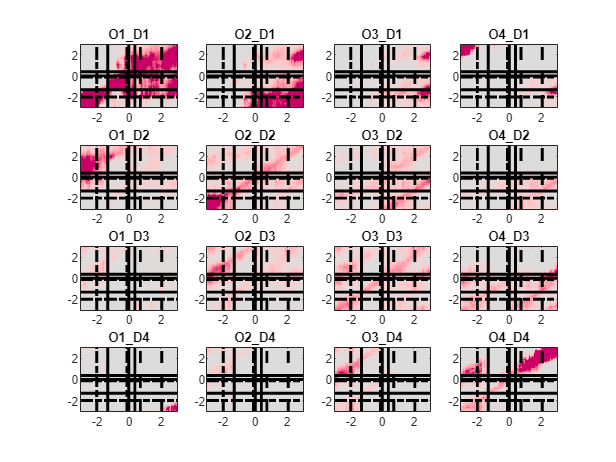

figure;
for z = 1:numel(groupDs)
    subplot(4,4,z);
    %     imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,median(zscore(groupDs{z},0,'all'),3), [-1 1]);
    imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,median(groupDs{z},3), [-0.5 0.5]);
    colormap(rbDivMap);
    hold on;
    set(gca, 'ydir', 'normal');
    [r,c] = ind2sub(mlb.seqLength, z);
    title(sprintf('O%i_D%i',r,c), 'interpreter', 'none');
    plot(repmat(median(cell2mat(trialLIGHTlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(get(gca,'xlim'), repmat(median(cell2mat(trialLIGHTlat(:)')), [1,2]), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialPIlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(get(gca,'xlim'), repmat(median(cell2mat(trialPIlat(:)')), [1,2]), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(get(gca,'xlim'), repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), '-.k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialPOlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(get(gca,'xlim'), repmat(median(cell2mat(trialPOlat(:)')), [1,2]), '-k', 'linewidth', 2);
    plot(repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(get(gca,'xlim'), repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), '-k', 'linewidth', 2);
    if strcmp(endTrialBound, 'RWD')
        plot(repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'PO')
        plot(repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'RS')
        plot(repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    end
    plot(repmat(median(cell2mat(trialPIlat(:)')) - median(cell2mat(prevTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
end


presentDs = reshape(groupDs(logical(eye(mlb.seqLength))), [1,1,mlb.seqLength]);
pastDs = reshape(groupDs(triu(true(mlb.seqLength),-1) & tril(true(mlb.seqLength),-1)),[1,1,mlb.seqLength-1]);
futureDs = reshape(groupDs(triu(true(mlb.seqLength),1) & tril(true(mlb.seqLength),1)),[1,1,mlb.seqLength-1]);


## Plot Past-Present-Future Decodings

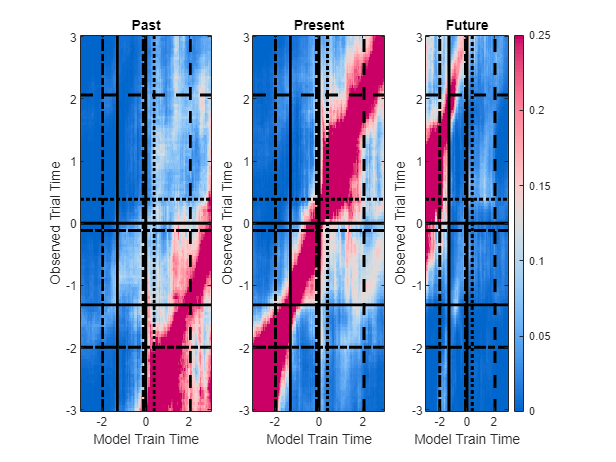

figure;
sp = nan(1,3);
sp(1) = subplot(1,3,1);
imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,median(cell2mat(pastDs),3),[-0 0.25]);
% imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,mean(zscore(cell2mat(pastDs),0,'all'),3),[-0.5 0.5]);
% imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,median(cell2mat(pastDs(1:end-1)),3),[-1 1]);
% imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,median(zscore(cell2mat(pastDs(1:end-1)),0,'all'),3),[-0.5 0.5]);
hold on;
set(gca,'ydir', 'normal');
colormap(cMap);
xlabel('Model Train Time');
ylabel('Observed Trial Time');
title('Past');
sp(2) = subplot(1,3,2);
imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,median(cell2mat(presentDs),3),[-0 0.25]);
% imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,mean(zscore(cell2mat(presentDs),0,'all'),3),[-0.5 0.5]);
% imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,median(cell2mat(presentDs(2:3)),3),[-1 1]);
% imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,median(zscore(cell2mat(presentDs(2:3)),0,'all'),3),[-0.5 0.5]);
hold on;
set(gca,'ydir', 'normal');
colormap(cMap);
xlabel('Model Train Time');
ylabel('Observed Trial Time');
title('Present');
sp(3) = subplot(1,3,3);
imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,median(cell2mat(futureDs),3),[-0 0.25]);
% imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,mean(zscore(cell2mat(futureDs),0,'all'),3),[-0.5 0.5]);
% imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,median(cell2mat(futureDs(2:end)),3),[-1 1]);
% imagesc(mlb.obsvTimeVect,mlb.obsvTimeVect,median(zscore(cell2mat(futureDs(2:end)),0,'all'),3),[-0.5 0.5]);
hold on;
set(gca,'ydir', 'normal');
% colormap(cMap);
colormap(rbDivMap);
xlabel('Model Train Time');
ylabel('Observed Trial Time');
title('Future');
colorbar
for p = 1:length(sp)
    plot(sp(p), repmat(median(cell2mat(trialLIGHTlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(sp(p), get(gca,'xlim'), repmat(median(cell2mat(trialLIGHTlat(:)')), [1,2]), '-.k', 'linewidth', 2);
    plot(sp(p), repmat(median(cell2mat(trialPIlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(sp(p), get(gca,'xlim'), repmat(median(cell2mat(trialPIlat(:)')), [1,2]), '-k', 'linewidth', 2);
    plot(sp(p), repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), get(gca,'ylim'), '-.k', 'linewidth', 2);
    plot(sp(p), get(gca,'xlim'), repmat(median(cell2mat(trialSIGlat(:)')), [1,2]), '-.k', 'linewidth', 2);
    plot(sp(p), repmat(median(cell2mat(trialPOlat(:)')), [1,2]), get(gca,'ylim'), '-k', 'linewidth', 2);
    plot(sp(p), get(gca,'xlim'), repmat(median(cell2mat(trialPOlat(:)')), [1,2]), '-k', 'linewidth', 2);
    plot(sp(p), repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), get(gca,'ylim'), ':k', 'linewidth', 2);
    plot(sp(p), get(gca,'xlim'), repmat(median(cell2mat(trialRWDlat(:)')), [1,2]), ':k', 'linewidth', 2);
    if strcmp(endTrialBound, 'RWD')
        plot(sp(p), repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
        plot(sp(p), get(gca,'xlim'), repmat(median(cell2mat(trialRWDlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'PO')
        plot(sp(p), repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
        plot(sp(p), get(gca,'xlim'), repmat(median(cell2mat(trialPOlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), '--k', 'linewidth', 2);
    elseif strcmp(endTrialBound, 'RS')
        plot(sp(p), repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
        plot(sp(p),  get(gca,'xlim'), repmat(median(cell2mat(trialSIGlat(:)')) + median(cell2mat(nxtTrlLats(:)')),[1,2]), '--k', 'linewidth', 2);
    end
    plot(sp(p), repmat(median(cell2mat(trialPIlat(:)')) + median(cell2mat(prevTrlLats(:)')),[1,2]), get(gca, 'ylim'), '--k', 'linewidth', 2);
    plot(sp(p), get(gca,'xlim'), repmat(median(cell2mat(trialPIlat(:)')) + median(cell2mat(prevTrlLats(:)')),[1,2]), '--k', 'linewidth', 2);
end